# ELABORATO 1 -  PRODOTTO SCALARE

# LO BRUTTO FABIO / MAIONE PAOLO

## DEFINIZIONE DEL PROBLEMA

Si vuole progettare un algoritmo in MPI per risolvere il prodotto scalare tra due vettori di reali, di dimensione N, su p processori.

In particolare si utilizza l'infrastruttura S.C.o.P.E. per permettere l'esecuzione del software in un ambiente parallelo.

## DESCRIZIONE DELL'ALGORITMO

In particolare le fasi dell'algoritmo, implementato nel file `elaborato_1.c`, sono:

1) Distribuzione dei due vettori in p processori: ognuno dei p processori eseguirà il prodotto scalare sulla porzione dei vettori ricevuti dal processo *root*, cioè quello con rank 0 ;

2) Elaborazione dei prodotti scalari parziali in parallelo ;

3) Combinazione dei prodotti scalari parziali nel processo *root* che determinerà il risultato finale.

A tal proposito sono state utilizzate le primitive fornite da MPI (rispettivamente per la prima fase `MPI_Scatterv()` e per la terza `MPI_Reduce()`).

Inoltre l'algoritmo progettato comprende anche il caso in cui la dimensione `dim` dei vettori non sia multipla del numero di processori p a disposizione.

Si è scelto di misurare i tempi di esecuzione nel processo di rank 0 usando la primitiva` MPI_Wtime()` tra la fase 2 e la fase 3 scegliendo il minimo tra 3 misurazioni ripetute.

Infine, si osservi che i controlli di robustezza del software sono stati interamente delegati al processo *root*.

## INPUT, OUTPUT E CONDIZIONI DI ERRORE

- **Input**: i due vettori `x` e `y` di cui effettuare il prodotto scalare, la loro dimensione (`dim`).

- **Output**: il prodotto scalare dei vettori x e y.

- **Condizioni di errore**: la dimensione dei vettori deve essere uguale per entrambi e deve essere un intero positivo non minore del numero di processori.

## ESEMPIO DI FUNZIONAMENTO

Nell'immagine seguente vi è un esempio di funzionamento, con 4 processori e dimensione dei vettori pari a ${10}^5$ .

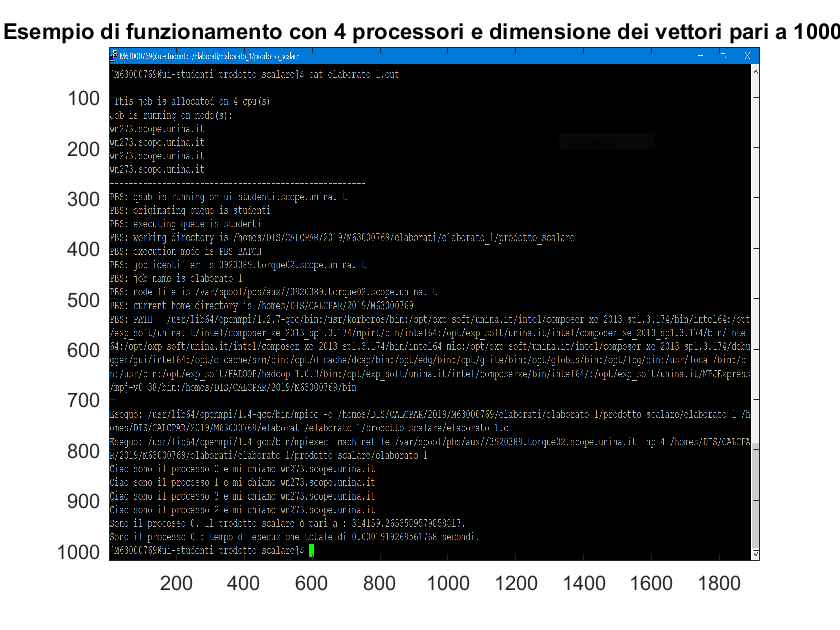

%esempio di funzionamento
funzionamento

## ESEMPI DI ERRORE

Nelle successivi immagini, invece, sono mostrati i messaggi di errore al verificarsi delle condizioni sopra citate.

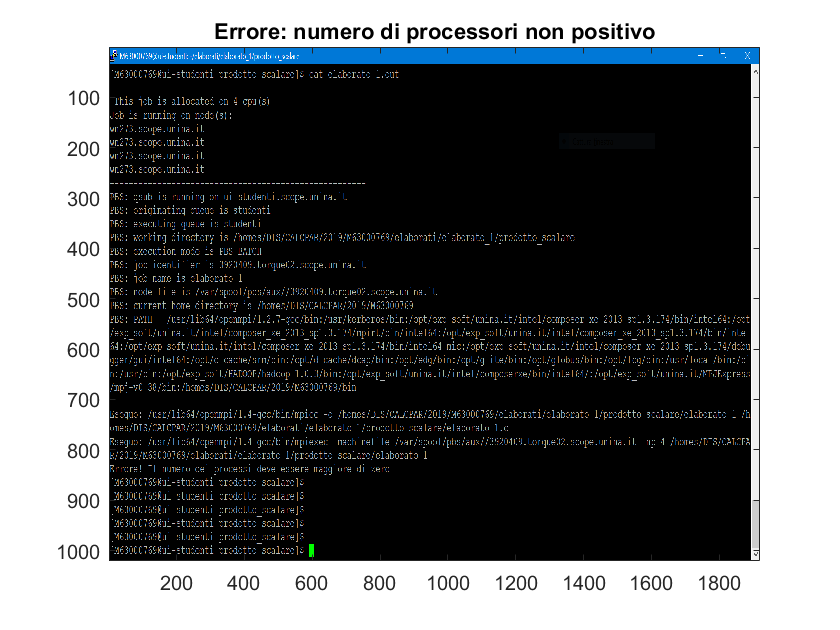

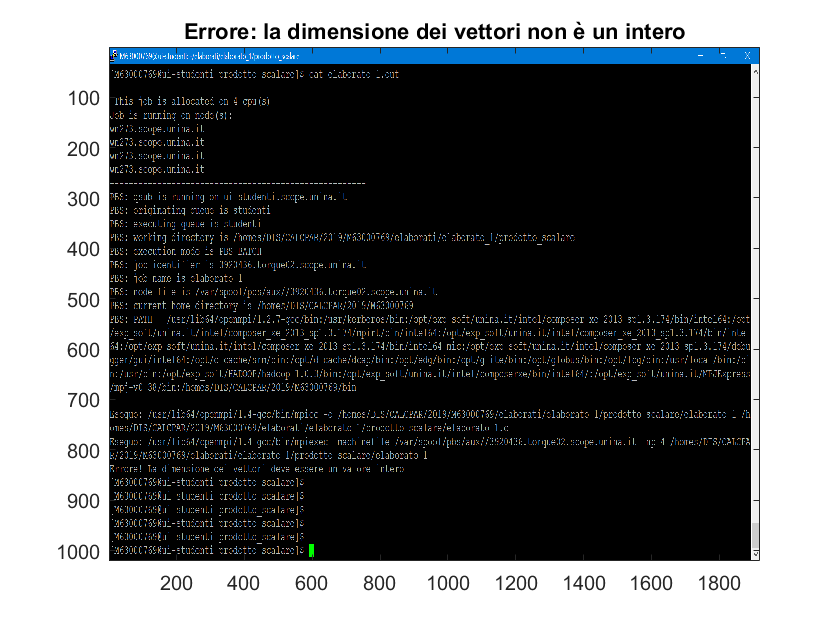

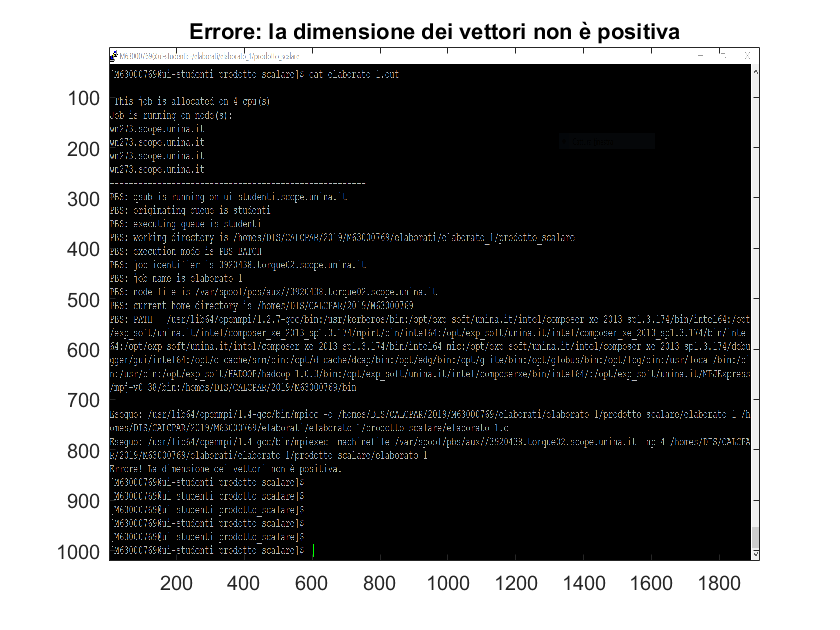

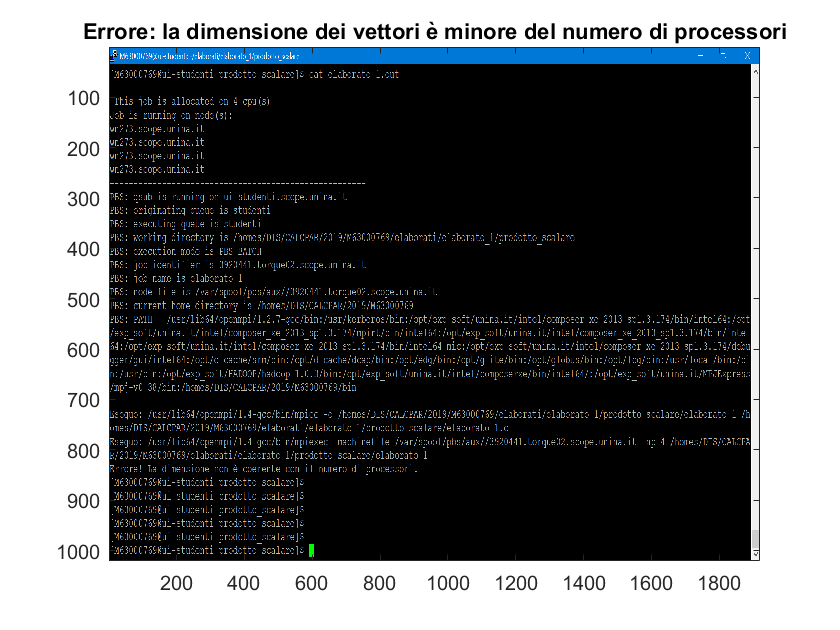

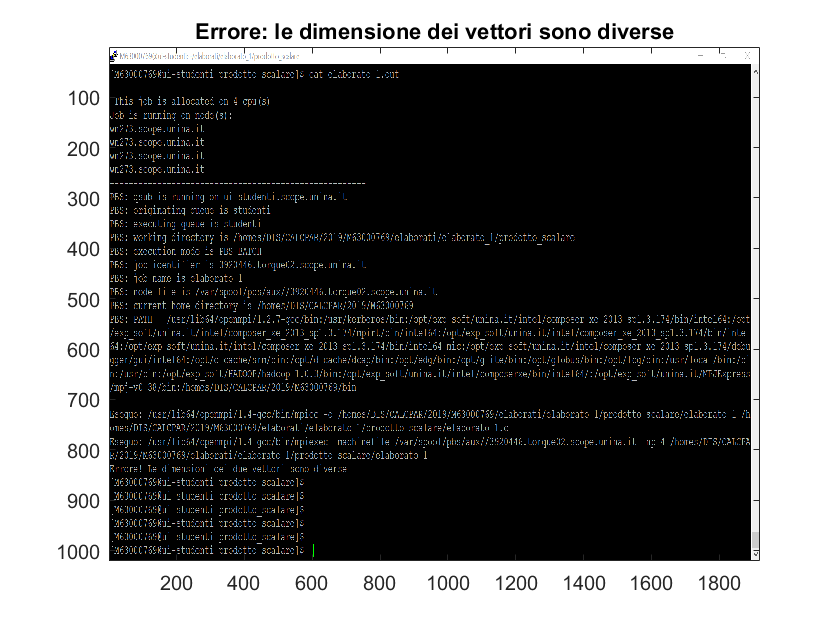

%un esempio per ciascuna condizione di errore
errori

## ANALISI DELLE PRESTAZIONI (T(p), S(p), E(p))

Di seguto per brevità si indicherà con p il numero di processori e con N la dimensione dei vettori x e y.

## Tempo di esecuzione - T(p)

Si è scelto di misurare i tempi di esecuzione nel processo* root* usando la primitiva `MPI_Wtime()`. In particolare l'intervallo di tempo misurato è quello che comprende le fasi 2 e 3 dell'algoritmo prima citate.

Per ciascuna misurazione (al variare di N da 10k a 100M e al variare di p da 2 a 16) è stato considerato il minimo tra 3 esecuzioni ripetute, eseguite in momenti diversi.

Di seguito si riportano i risultati in forma di tabelle e grafici.

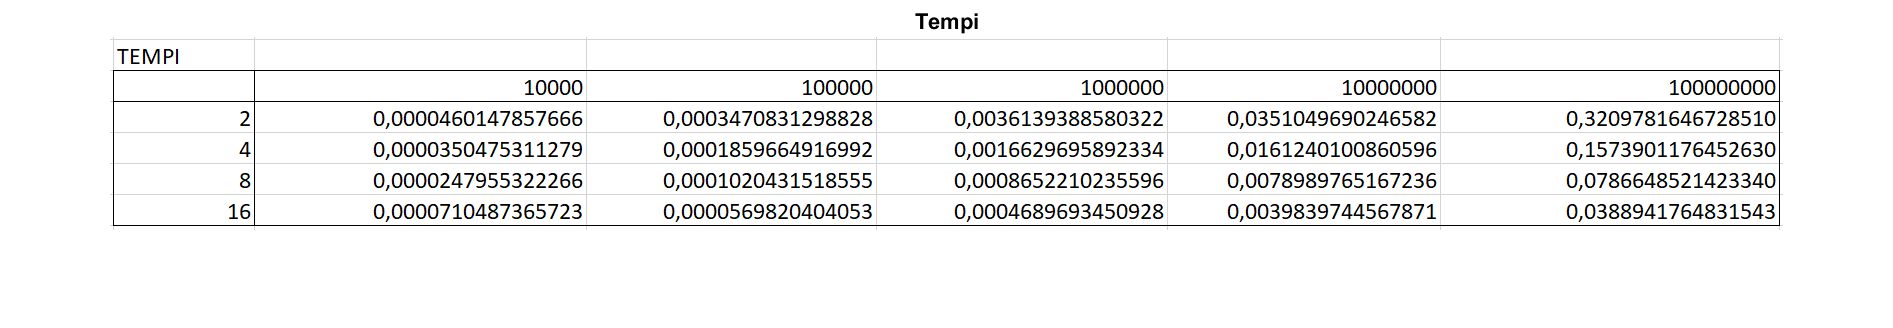

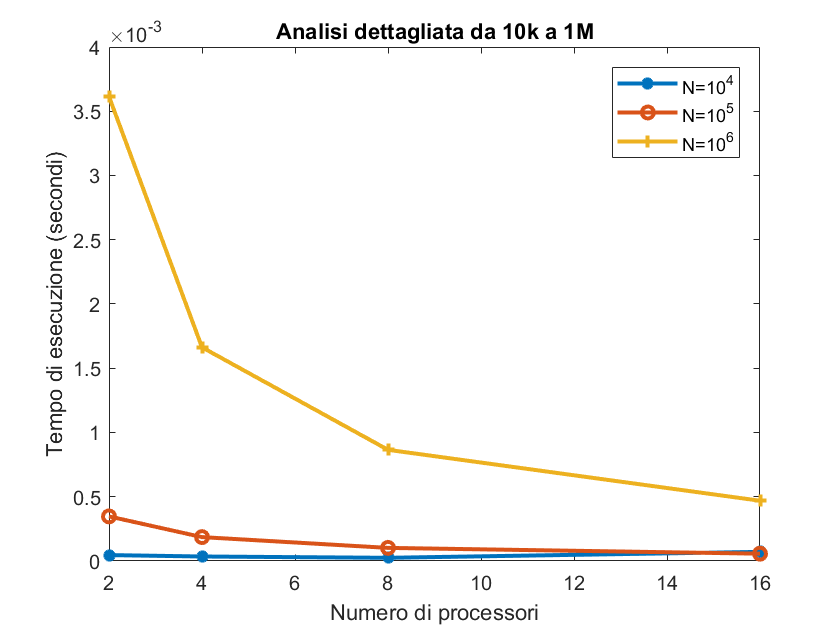

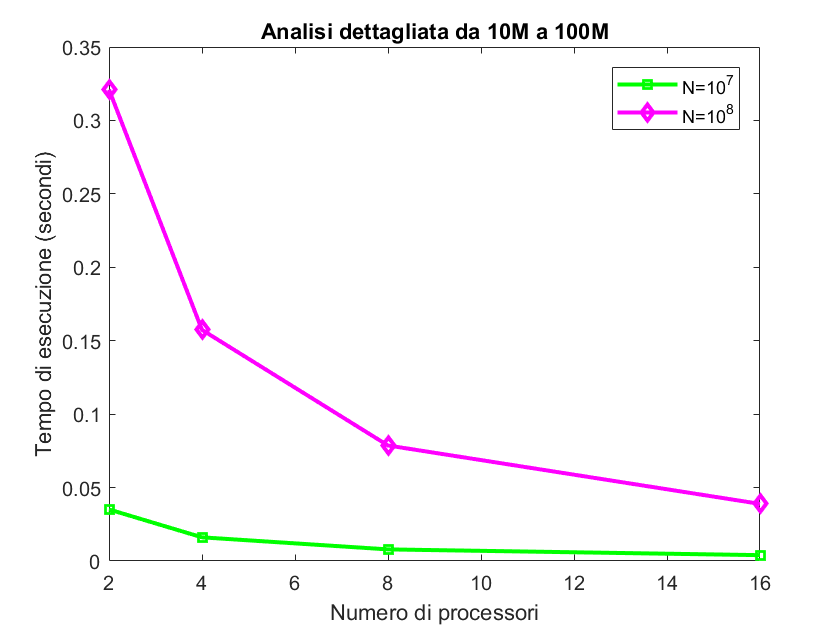

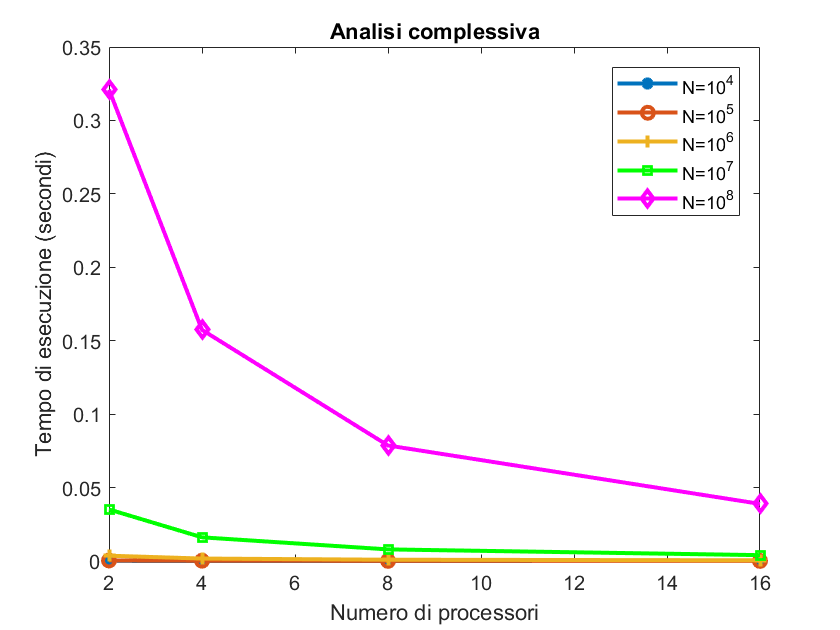

%esecuzione script per tabelle e grafici
tempi

L'ultimo grafico è quello che riassume i risultati ottenuti per tutti i possibili valori di N e p. Sono forniti due ulteriori grafici (i primi due) che mostrano gli andamenti più nel dettaglio.

Per considerazioni più di dettaglio su questi risultati si rimanda alla sezione Conclusioni.

## Speed up ed Efficienza - S(p) ed E(p)

Si è calcolato, inoltre, il tempo di riferimento T(1) che corrisponde al tempo di esecuzione su un unico processore.

A partire dai tempi misurati nella sezione precedente e da T(1) è stato calcolato lo speed-up al variare di N e p.

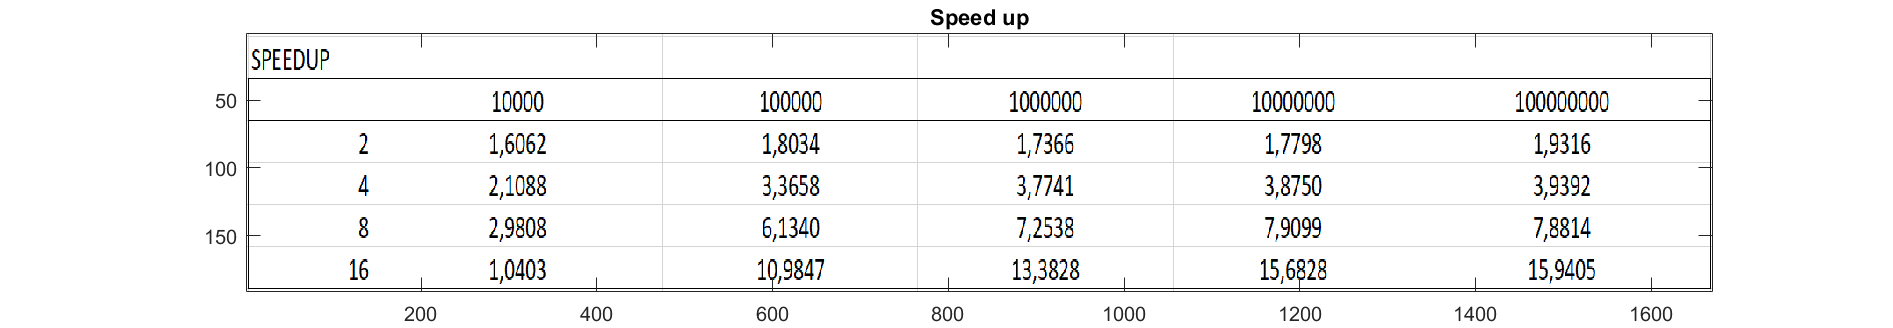

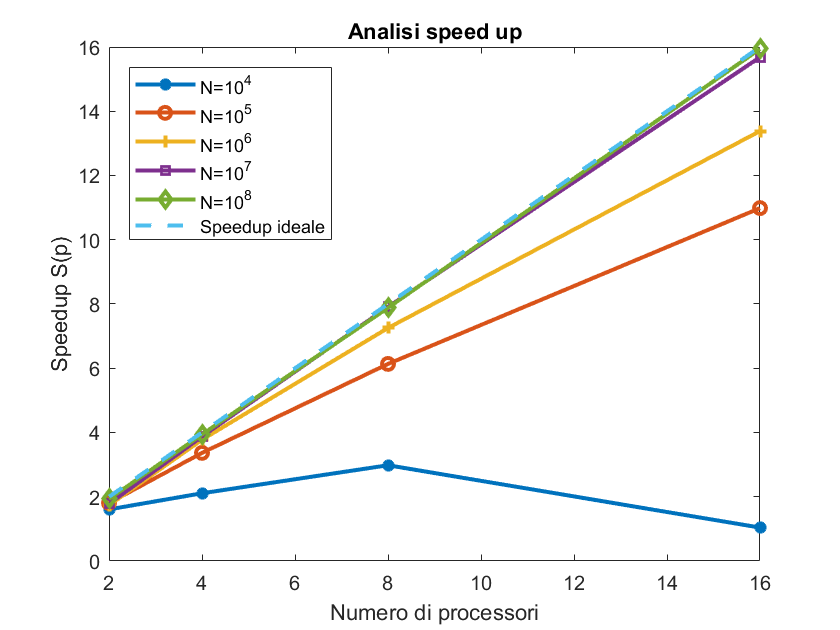

%esecuzione script per tabelle e grafici
speedup

Infine si è calcolata l'efficienza rapportando lo speed-up S(p) al numero di processori p.

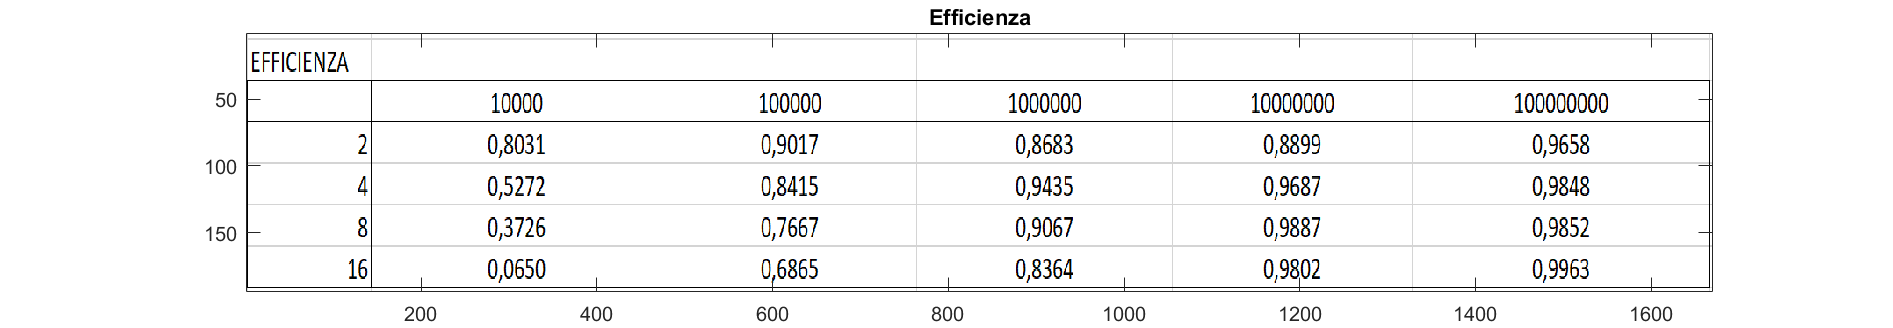

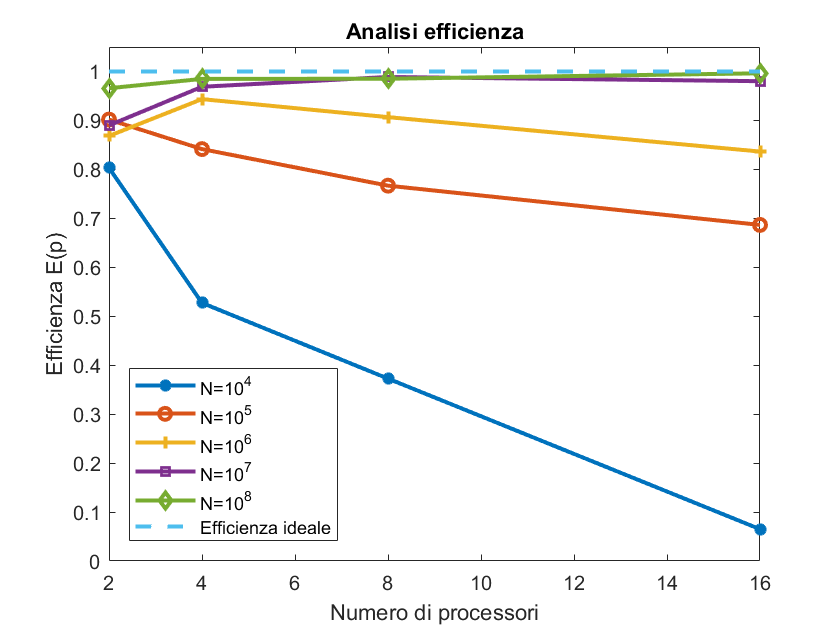

%esecuzione script per tabelle e grafici
efficienza

## Conclusioni

Dai grafici appena presentati si possono trarre alcune considerazioni.

Analizzando l'efficienza si nota come nel caso N=${10}^4$ e N=${10}^5$  l'efficienza ottimale si ha per 2 processori.

Invece nel caso di N=${10}^6$ l'ottimo è in corrispondenza di 4 processori, mentre per N=${10}^7$ e N=${10}^8$ è, rispettivamente, in corrispondenza di 8 e 16 processori.

Si possono fare ulteriori considerazioni notando che, per N fissato, l'efficienza peggiora dopo un certo valore di p (ciò verifica sperimentalmente la legge di Amdahl), e che, in generale, all'aumentare sia di N che di p, l'efficienza migliora (verificando la legge di Gustafson).

Analoghe considerazioni per i tempi e lo speedup.

## ANALISI DELL' ACCURATEZZA

Confrontando il risultato ottenuto sul cluster Scope e quello ottenuto su MATLAB si ottiene il seguente errore relativo, fissando a 8 il numero di processori con dimensione dei vettori pari a ${10}^5$.

%esecuzione script per i test di accuratezza
accuratezza

risultato_scope =      3.141592653589620e+05


risultato_matlab =      3.141592653587123e+05


errore_relativo =      7.946690904462235e-13
